# Control via Controller Canonical Form

## 4.5 Continous Control via Controller Canonical Form

format short

A = [-0.14 0.33 -0.33;
     0.1 -0.28 0;
     0 1.7 -0.77];
B = [0;0;-0.025];
C = [2 0 0];
D = 0;
eigopen = eig(A)

eigopen =   -0.1457 + 0.2157i
  -0.1457 - 0.2157i
  -0.8986 + 0.0000i


% examine the controllability
Mc = ctrb(A,B);
rank(Mc)

ans = 3

eigclose = [-0.67 -0.67 -0.67];
alpha = poly(eigclose)% c a2 a1 a0

alpha =     1.0000    2.0100    1.3467    0.3008


**Using controller canonical form**

%% Transfer system to canonical form
chapo = poly(A);% c a2 a1 a0
p1 = B;
p2 = A*p1+chapo(2)*p1;
p3 = A*p2+chapo(3)*p1;
P = [p3 p2 p1]

P =     0.0023    0.0083         0
    0.0008         0         0
   -0.0002   -0.0105   -0.0250


Acc = P^(-1)*A*P

Acc =     0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000
   -0.0609   -0.3296   -1.1900


Bcc = P^(-1)*B

Bcc =    -0.0000
   -0.0000
    1.0000


Ccc = C*P

Ccc =     0.0046    0.0165         0


Dcc = D

Dcc = 0

%% Find K
Kcc = fliplr(alpha-chapo);
Kcc = Kcc(1:3)

Kcc =     0.2399    1.0171    0.8200


K = Kcc*P^-1

K =    81.5394   56.3018  -32.8000


A_K = A-B*K;
eig(A_K) % sometimes the results here will not be precise due to round off errors

ans =   -0.6700 + 0.0000i
  -0.6700 - 0.0000i
  -0.6700 + 0.0000i


%% step response without controller
[num,den] = ss2tf(A,B,C,D)

num =          0         0    0.0165    0.0046


den =     1.0000    1.1900    0.3296    0.0609


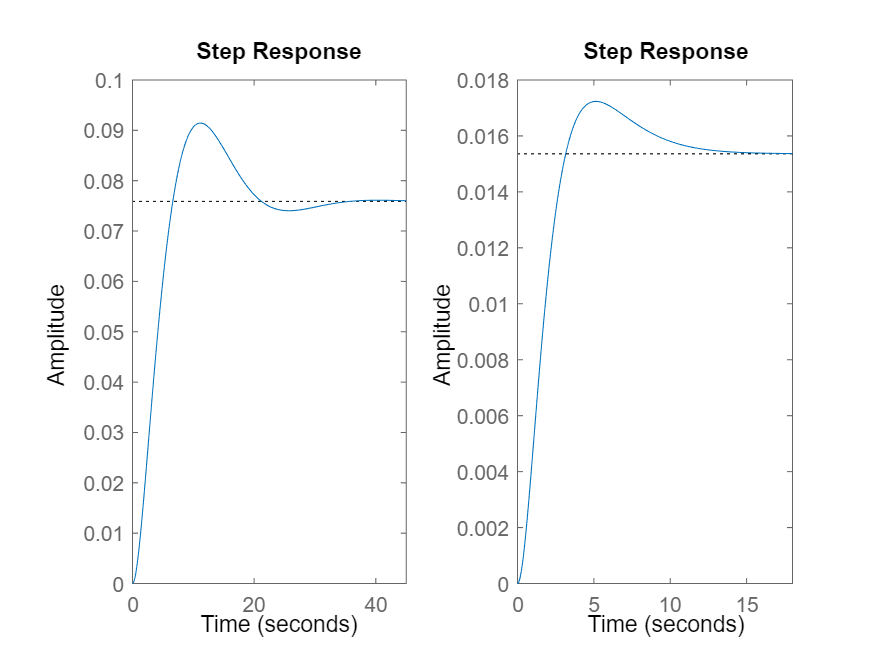

G = tf(num,den);
figure
subplot(1,2,1)
step(G)
% step response with controller
[num,den] = ss2tf(A_K,B,C,D);
Gc = tf(num,den);
subplot(1,2,2)
step(Gc)

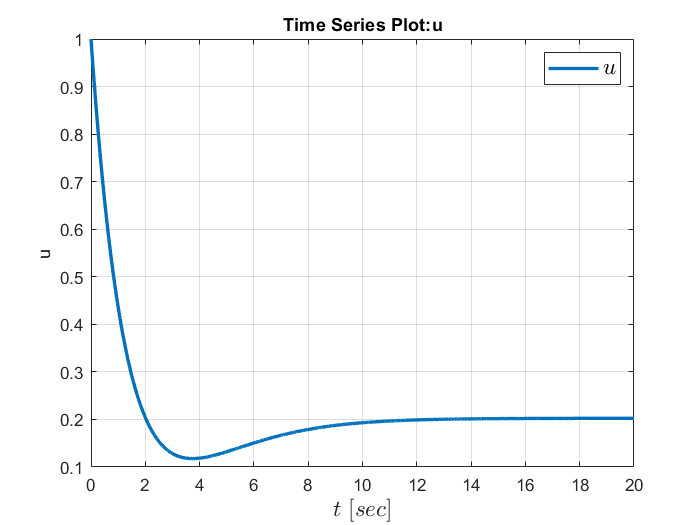

sim("ContinousControl.slx")
figure
plot(u, 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$u$'}, 'Interpreter', 'latex', 'FontSize', 14);
grid;

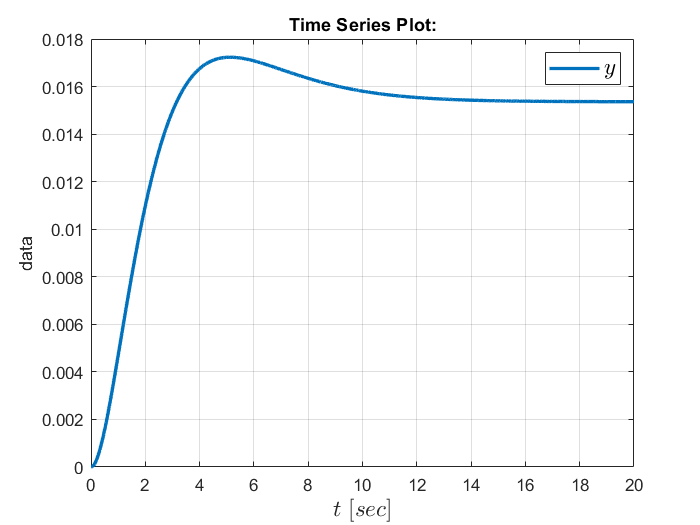

figure
plot(y, 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$y$'}, 'Interpreter', 'latex', 'FontSize', 14);
grid;

## 4.6 Discrete Control via Controller Canonical Form

Ts = 0.2;
F = expm(A*Ts)

F =     0.9730    0.0529   -0.0603
    0.0192    0.9461   -0.0006
    0.0031    0.3063    0.8572


[F,G]=c2d(A,B,Ts)

F =     0.9730    0.0529   -0.0603
    0.0192    0.9461   -0.0006
    0.0031    0.3063    0.8572


G =     0.0002
    0.0000
   -0.0046


eigclose_d = exp(eigclose*Ts)

eigclose_d =     0.8746    0.8746    0.8746


%% examine the controllability
Mc = ctrb(F,G);
rank(Mc)

ans = 3

% Apply Ackermann's Formula
chapod = poly(eigclose_d)

chapod =     1.0000   -2.6238    2.2947   -0.6690


chap_Fk = F^3+chapod(2)*F^2+chapod(3)*F+chapod(4)*eye(3)

chap_Fk =     0.0008   -0.0016   -0.0005
    0.0004    0.0002   -0.0002
    0.0009    0.0015   -0.0004


K = [0 0 1]*Mc^-1*chap_Fk

K =    74.6336   47.7193  -30.3934


% same answer with acker()
K_ack = acker(F,G,eigclose_d)

K_ack =    74.6336   47.7193  -30.3934


eig(F-G*K)

ans =    0.8746 + 0.0000i
   0.8746 - 0.0000i
   0.8746 + 0.0000i


% verify the origin system eigenvalues
eig_ori = 1/Ts*log(eig(F-G*K))

eig_ori =   -0.6700 + 0.0000i
  -0.6700 - 0.0000i
  -0.6700 + 0.0000i


## 4.12 Integral Control of a Third Order System

A1 = [A zeros(3,1);-2 0 0 0]

A1 =    -0.1400    0.3300   -0.3300         0
    0.1000   -0.2800         0         0
         0    1.7000   -0.7700         0
   -2.0000         0         0         0


B1 = [B;0]

B1 =          0
         0
   -0.0250
         0


Br = [0;0;0;1]

Br =      0
     0
     0
     1


C1 = [C 0]

C1 =      2     0     0     0


lambda_cl = [-0.67 -0.67 -0.67 -0.67];
K1 = acker(A1,B1,lambda_cl)

K1 =   210.6667  -88.9490  -59.6000  -43.6171


K = K1(1:3)

K =   210.6667  -88.9490  -59.6000


Ki = -K1(4)

Ki = 43.6171

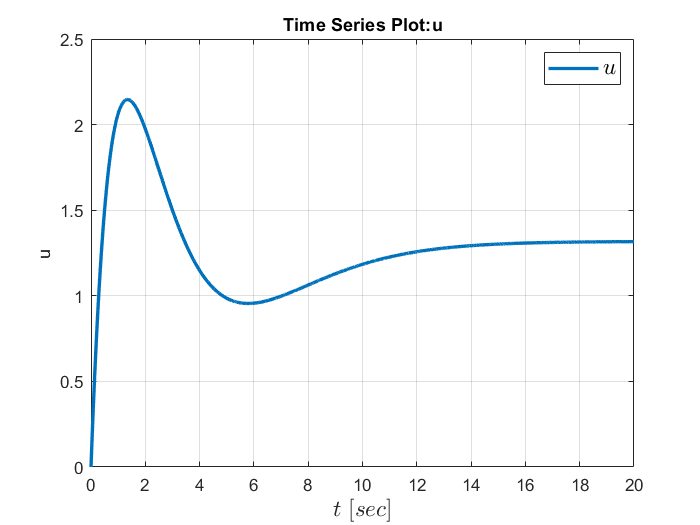

A1_k = A1 - B1*K1;

% simulation
x0 = [0;0;0];
xi = 0;
SIM_TIME = 20;
SIM_STEP = 0.005;
sim('IntegralControl.slx')

figure
plot(u, 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$u$'}, 'Interpreter', 'latex', 'FontSize', 14);
grid;

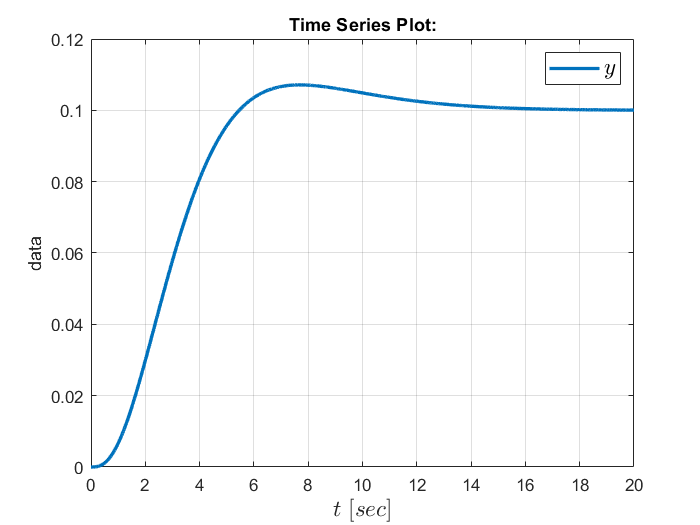

figure
plot(y, 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$y$'}, 'Interpreter', 'latex', 'FontSize', 14);
grid;

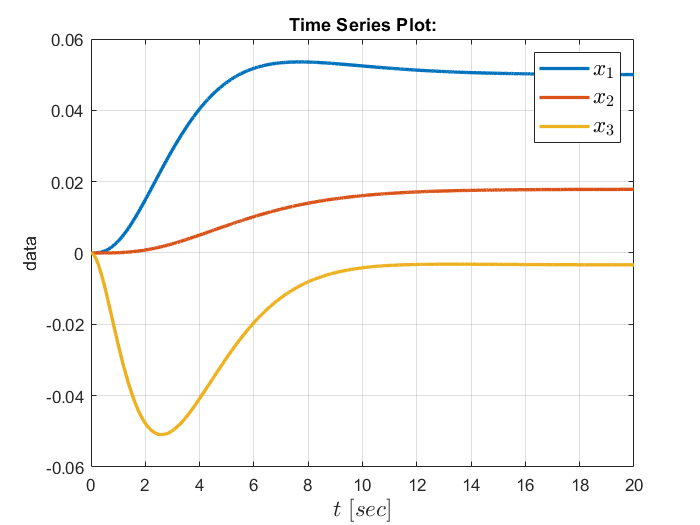


figure
plot(states(:,:), 'LineWidth', 2);
xlabel('$t \; [sec]$', 'Interpreter', 'latex', 'FontSize', 14);
legend({'$x_1$', '$x_2$', '$x_3$'}, 'Interpreter', 'latex', 'FontSize', 14);
grid;

% discrete
F1 = [F zeros(3,1);-2*Ts 0 0 1];
G1 = [G;0];
lambdai_cl = [-0.67 -0.67 -0.67 -0.67];
lambdai_cld = exp(lambdai_cl*Ts);
K1_case1 = acker(F1,G1,lambdai_cld)

K1_case1 =   193.7824  -77.5489  -53.4893  -37.6443


lambdai_cl2 = [-0.35 -0.35 -0.35 -0.35];
lambdai_cld2 = exp(lambdai_cl2*Ts);
K1_case2 = acker(F1,G1,lambdai_cld2)

K1_case2 =    37.9906  -38.3576   -8.8087   -3.1792


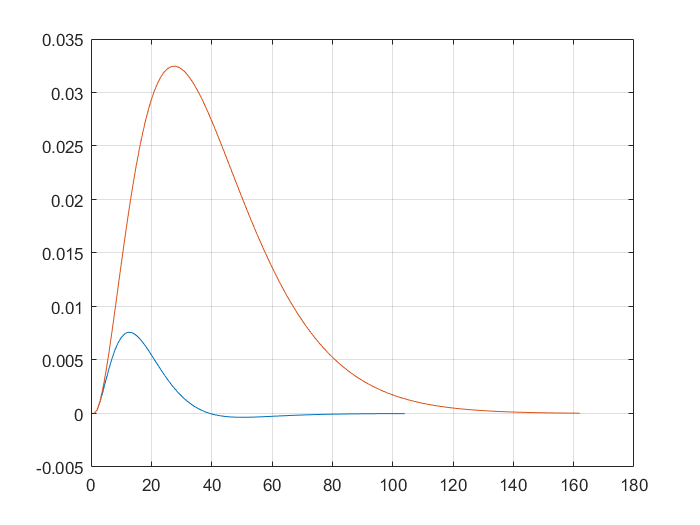

F_K1 = F1 - G1*K1_case1;
[num,den] = ss2tf(F_K1,G1,C1,D,1);
Gci_case1 = tf(num,den,Ts);

F_K2 = F1 - G1*K1_case2;
[num,den] = ss2tf(F_K2,G1,C1,D,1);
Gci_case2 = tf(num,den,Ts);


plot(step(Gci_case1))
hold on
grid on
plot(step(Gci_case2))
hold off

## 4.17 Discrete Observer for SISO System

The observer should be much faster than the system

eig_obsv = [-5 -3.5+3.5i, -3.5-3.5i];
Ts = 0.2;
eigd_obsv = exp(eig_obsv*Ts)

eigd_obsv =    0.3679 + 0.0000i   0.3798 + 0.3199i   0.3798 - 0.3199i


chapod = poly(eigd_obsv)

chapod =     1.0000   -1.1275    0.5260   -0.0907


chap_FL = F^3+chapod(2)*F^2+chapod(3)*F+chapod(4)*eye(3)

chap_FL =     0.2759    0.0291   -0.0591
    0.0216    0.2457   -0.0025
    0.0128    0.2865    0.1607


Mo = obsv(F,C)

Mo =     2.0000         0         0
    1.9459    0.1059   -0.1206
    1.8949    0.1662   -0.2208


L = chap_FL*Mo^-1*[0;0;1]

L =     0.8244
   -8.8262
  -15.4923


L_acker = acker(F',C',eigd_obsv)'

L_acker =     0.8244
   -8.8262
  -15.4923


## 4.20 Reduced Order Observer for a Third Order System

A11 = A(1,1)

A11 = -0.1400

A12 = A(1,2:3)

A12 =     0.3300   -0.3300


A21 = A(2:3,1)

A21 =     0.1000
         0


A22 = A(2:3,2:3)

A22 =    -0.2800         0
    1.7000   -0.7700


C1 = C(1,1)

C1 = 2

Mo = obsv(A22,C1*A12)

Mo =     0.6600   -0.6600
   -1.3068    0.5082


rank(Mo)

ans = 2

lambda_red = [-3.5+3.5i -3.5-3.5i];
L_red = acker(A22',(C1*A12)',lambda_red)'

L_red =   -28.3226
  -37.3377


% verify
lambda_asg = eig(A22-L_red*C1*A12)

lambda_asg =   -3.5000 + 3.5000i
  -3.5000 - 3.5000i
